# ***Processing MD Simulations Into the Necessary Format for Fitting Reflectivity Data.***

### *Scattering of Neutrons.*

In order to use MD simulations from bilayers to fit reflectivity data, there are a few processes which need to be done on the MD simulations first. Largely, this is because reflectivity is essentially a '1D' technique. It is sensitive to the averaged structure of the simulation in the *z* direction (normal to the membrane) and contains no information about the *xy* organisation. Information about the in plane structure of the membrane is averaged into a 1D 'projection' of the whole membrane structure in the z direction, and so in-plane information is largely lost.

The key parameter for neutron reflection (indeed, any neutron scattering) is the Scattering Length Density (SLD) profile. Neutron SLD in a given (in the reflectivity case) by the sum of the bound coherent neutron scattering cross sections (usually denoted by *b*) for each of the atoms in that volume. The scattering cross section essentially gives the strengh of interaction between incoming neutrons and the nucleii. There are varions types of scattering length (e.g. spin, or magnetic)  but the coherent SL is used because we are interested in elastic scattering, where the energy (wavelength)  of the neutron is conserved during scattering, as opposed to for example to the inelastic case, where energy is transferred to the nucleus.

The Neutron scattering lengths are different for each element, and can vary considerably between different isotopes. For biological applications, the ones of interest are usually:

*bc *= 0.6646e-4;	(Carbon)

*bo* = 0.5843e-4;	(Oxygen)

*bh* = -0.3739e-4;	(Hydrogen)

*bp* = 0.513e-4;	        (Phosphorus)

*bn* = 0.936e-4;	        (Nitrogen)

*bd *= 0.6671e-4;       (Deuterium)

These have units of Angstroms, hence scattering 'length'. Notice the very large difference between the SL of Deuterium and Hydrogen. This has huge censequence for Biology, as deuteration (of lipids, proteins or bulk water) can massively change the SLD profile, whilst having minimal effect on structure. This means that individual components in mixtures can effectively be highlighted, and also promotes a unique solution from the analysis. Typically, a neutron reflection experiment will involve measuring the same system at different deuterations, which the resulting datasets analysed simultaneously. The individual deuterations are referred to as 'contrasts'.

The SLD of a given volume of space is  given by:

$\rho =\sum_i \frac{n_i b_i }{V}$,      (1)                                                                                                                                                                                                                          

where V is the volume, where n is the number of the i'th type of atom in that volume, and bi the relevant cross sections. So for example, for D2O (assuming a volume of about 30$Å^{3\;\;} \textrm{or}\;\textrm{so}$)

$\rho_{D_2 O} =\frac{2b_D +b_O }{V_{H_2 O} }\simeq \frac{2\times 0\ldotp 67e^{-4} +0\ldotp 58e^{-4} }{30}=6\ldotp 4e^{-6} \;\;Å^{-2}$         (2)                                                                                                                                                   

### *1D Representation of an MD Simulation.*

We have established that in order to calculate the specular reflectivity from a bilayer membrane, we first need the projection of the bilayer structure from 3 dimesnions to a 1D representation. To do this, we follow the method of Petrache *et al* [1] exactly. 

Firstly, we do not consider the membrane atomostically (although this is in principle possible), but we follow the typical procedure of soft matter neutron scattering of splitting the lipids into 'submolecular fragments'. This is because it is far more natural from a biochemistry perspective to think of lipids as 'heads' and 'tails' - or usually smaller sub-fragments of these - than it is to think of lipids atom by atom. We follow the general procedure of Wiener and White [2], which parses the headgroups into a series of fragments which might reasonably be expected to behave as single units, and similarly for the tails. So for DPPC, their scheme would divide the lipids as: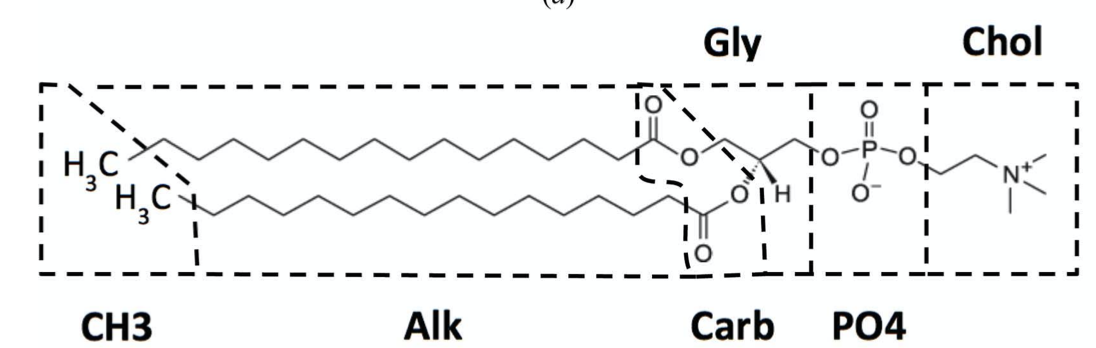

This has become the accepted way to parameterise lipids for scattering analysis, and we stick to this convention (although in practice for neutrons we would tend to group the PO4 and Choline groups into 1, since they are difficult to distinguish)

In order to obtain a 1D projection of the MD simulation, we need to consider the positions of these groups for *all* the lipids within the membrane, and represent these as 1D distributions. When you think about this, it's clear why this whould be. For any simulation, the lipids do not all stack up neatly into rows, with each fragment neatly aligned across the mebrane. Rather, there is significant disorder, both with individual lipids showing small displacements along the z direction, but also due to inherent fluctuations within the membranes themselves. This disorder is critical for an accurate representation of the membrane for scattering, and for the consideration of it's physical properties. To capture this variation we introduce the concept of Number Density (ND) [1][2]. These are distributions, showing the overall 'spread' of positions of individual components across the whole simulation.

The procedure is to first chose a coordinate system so that the bilayer lies in the xy plane, and the z-direction is along the bilayer normal. We then divide our somulation into a series of of slices of thickness $\Delta z$, and simply count the number of occurances of each group in each slice, $N\left(z\right)$. Then we form a histogram of the number of occurances in each slice (there are various ways of defining 'occurance', discussed in Petrache. Valeria ha sfound success using their 4th option of counting electrons)

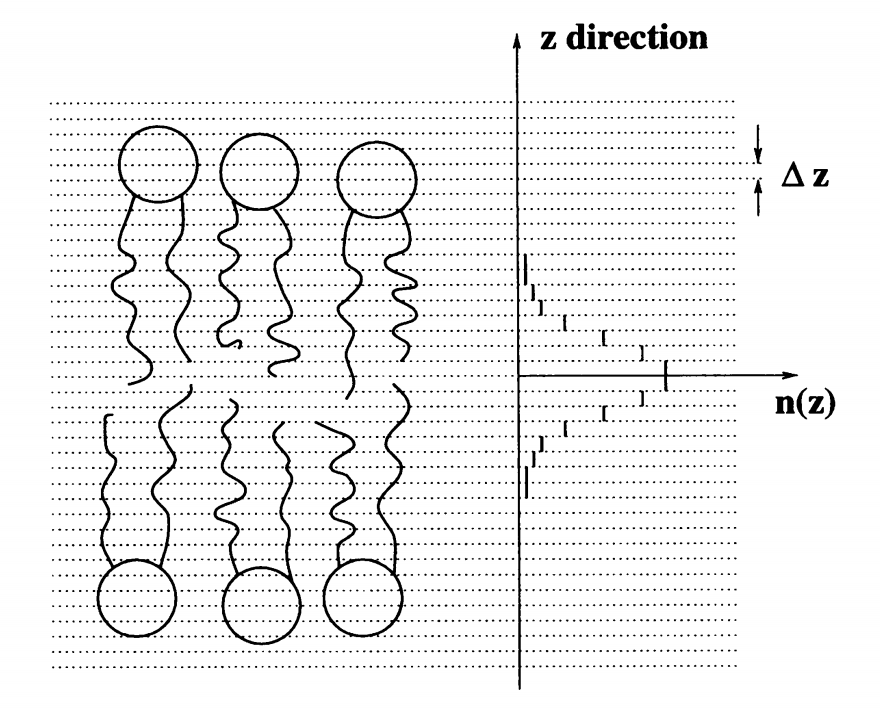

Then, to obtain the number density (which we do to have consistancy between simulations of different sizes) we simply divide $N\left(z\right)$ by the slice volume:

$n\left(z\right)=\frac{N\left(z\right)}{V_s }$.      (3)                                                                                                                                                                                                                          

Doing this for a typical simulation, we then obtain distributions for each of our submolecular fragments, which capture the 1D the positional variation of each fragment across the simulation:

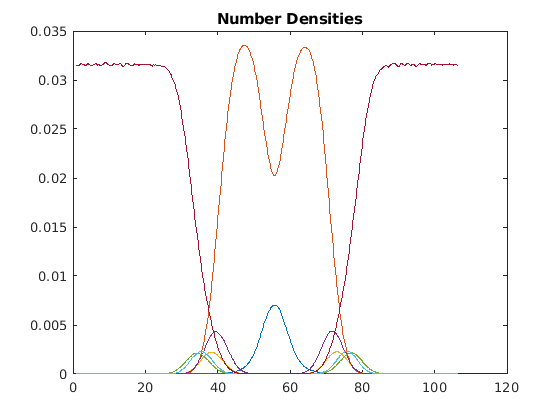

load('DPPC_Number_Densities');
z = ND.z;           
nTot = ND.nTot;         % This is an array containing the n(z) distributions for all the components

%figure(1)
clf; hold on; title('Number Densities'); box('on');
for i = 1:size(nTot,2)
    nTot(:,i) = smooth(nTot(:,i),4);
    plot(z,nTot(:,i));
end

This is the starting point for the reflectivity calculation, and the simulation is usually processed to this step by the MD codes.

### *From ND to SLD*

Whilst ND is a starting point for converting our simulation into an SLD profile, to go further we need information about volume. Since we are working with groups of atoms, then we need the volume per fragment. It's tempting to think that these would come directly from the simulation, but as discussed in detail in Petrache [1], it doesn't seem to be that simple. Essentially,  one intuitive way would be to define dividing surfaces between adjacent molecules and go form there, but the specification of the dividing surfaces is rather arbitrary, and would inevitably leave void volumes. This is not what is required for scattering - (1) refers to the toal volume, irrespective if that contains voids as we would understand them from a lipid packing sense or not.

For a system where there are two components, *A* and *B*, if we consider the volume within each slice, then for space filling we need

$V_A N_A \left(z\right)+V_B N_b \left(z\right)=V_S$.         (4)                                                                                                                                                                                                       

where $V_A$ and $V_B$ are the volumes we are looking for. To understand this, remember that the $N_x$ are distributions, so the *z* dependence gives the fraction of the total number of each component itn each slice. Then multiplying this by the component volume will give how much of this total volume is in each slice. If those add up give the total volume of the slice, then you have space filling.

But we need to work with the number densities, and to get there we can divide everything by the slice volume, to get

$V_A n_A \left(z\right)+V_B n_B \left(z\right)=1$.         (5)                                                                                                                                                                                                      

The quantities $V_x n_x \left(z\right)\;$are known as Volume Fractions. Alternatively, these are referred to as probabilities - $p_x \left(z\right)=V_x n\left(z\right)$ -  because the sum in eq (5) *at each point in z* must equal to 1. The terms Volume Fraction and Probability are used interchangeably.

To obtain the values for re relevant component volumes, we need to find values for the volumes so that eq (5) is satisfied at each point in z (i.e. that $\sum_i p_i \left(z\right)=1$ is true across the whole z direction of the simulation). We do this by iteratively fitting 

$F_T =\sum_z \left\lbrack \sum_i p_i \left(z\right)-1\right\rbrack$.            (6)                                                                                                                                                                                           

In other words, perfect determination of $V_i \;$should make $F_T$ zero everywhere, but this is never quite true. We iterate to get it as small as possible (i.e. the best possible space filling for our distributions). 

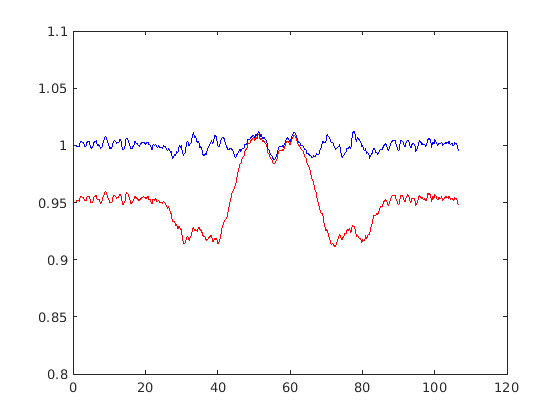

% Calculation of Volumes

% First, we define a set of approximate 'guess' volumes for the
% components (we get these from various literature sources, which
% often disagree, so these are approximate).
vCh3 = 59;
vCh2 = 28.1;
vGlyc = 68.8;
vCoo = 39;
vChol = 120;
vPo4 = 54;
vWat = 30.2;

% Put these into a single array
volumes = [vCh3 vCh2 vGlyc vCoo vChol vPo4 vWat];

% Calculate some initial probabilities from these for later comparison
% (see 'Function Definitions' at the end of this document for details).
[probs,guessProb] = calcProbs(z,nTot,volumes);

% In the fit, the volumes are our fitting parameters.
% The target funtion also needs to know about nTot and z however (for use in the
% 'calcProbs' function). An easy way to do this is to just put them in
% the Matlab base workspace and then they are accessible for any function in
% this Matlab session
setappdata(0,'z',z);        % 0 denotes the base workspace
setappdata(0,'nTot',nTot);

% We will do the minimisation using Matlab's in-built Simplex.
% The target function (i.e. the one to be minimised) is defined
% in 'fitFun' (see function definintions at the end of the document)
OPTIONS = optimset('MaxFunEvals',Inf,'Display','off');
fitVols = fminsearch(@fitFun,volumes,OPTIONS);

% Calculate the total probabilty from the fit, and plot to compare with
% that from our initial guess...
[probs,fitProb] = calcProbs(z,nTot,fitVols);

figure(2); clf; box('on'); 
plot(z,guessProb,'r-');
hold on
plot(z,fitProb,'b-'); ylim([0.8 1.1]); 

To calculate the SLD's, we simply apply equation (1) for each component...

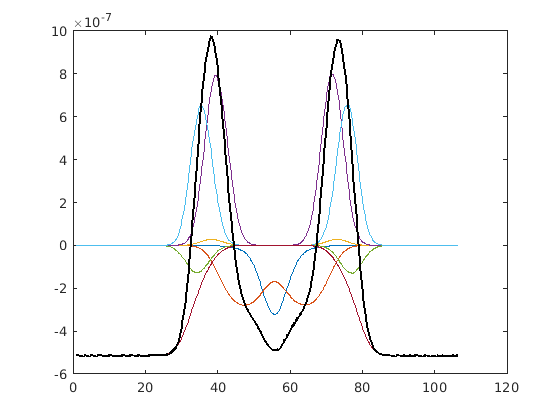

%First define all the neutron scattering lengths...
bc = 0.6646e-4;	    %Carbon
bo = 0.5843e-4;	    %Oxygen
bh = -0.3739e-4;	%Hydrogen
bp = 0.513e-4;	    %Phosphorus
bn = 0.936e-4;	    %Nitrogen
bd = 0.6671e-4;	    %Deuterium

%Work out the total scattering length in each fragment....
COO = (2*bo) + (1*bc);
GLYC = (3*bc) + (5*bh);
CH3 = (1*bc) + (3*bh);              
PO4 = (1*bp) + (4*bo);
CH2 = (1*bc) + (2*bh);
H2O = (2*bh) + (1*bo);
D2O = (2*bd) + (1*bo);
CHOL = (5*bc) + (13*bh) + (1*bn);

% Make a vector of these for convenience
scatLengths = [CH3 CH2 GLYC COO CHOL PO4 H2O];

% The way we have defined the groups, we make a mask
% defining how many of each are in the whole molecule.
% So, there are 2CH3's and 2COO.
% (CH2 and H2O are slightly different - even though there are
% 28 CH2's in DPPC, we are working with volume per CH2, not
% volume per chain, so we do the same with our mask).
nComponents = [2 1 1 2 1 1 1];

% Now we work out the SLD's
% Pre-allocate arrays
sld = zeros(size(probs));               % To hold individual SLD's
totSLD = zeros(size(probs,1),1);        % To hold the total overall SLD

% Calculate SLD's
for i = 1:size(probs,2)
   sld(:,i) = (probs(:,i).*(nComponents(i)*scatLengths(i)))./(nComponents(i)*fitVols(i));   % Equation 1
   totSLD = totSLD + sld(:,i);
end

% Plot this out..
figure(3); clf; hold on; box on
for i = 1:size(probs,2)
    plot(z,sld(:,i));
end
plot(z,totSLD,'k-','LineWidth',2.0);

From here, we then need to incorporate the above into a model for the interface  so that we can calculate the reflectivity. Reflectivity is a function of the entire interface - it is not possible to isolate the bilayer signal from the whole, and we have to consider everything that is in the beam. As mentioned earlier, we also need to measure the membrane at different deuterations to tend towards a unique solution for the fit. In practice, we do this by measuring the same membrane against three or more 'water contrasts'. This relies on the large difference in cross section between Hydrogen and Deuterium. So, we measure the sample against D2O and H2O, and usually a mixture of both. So, from the plot above you can see that H2O has a Scattering Length Density of around -0.56e-6. The SLD of D2O is 6.35e-6, and a 50/50 mixture of both will be about 2.9e-6. 

To give us the flexibility to have any water deuteration level in out plots, we take the SLD and probabilites of the bilayer only - i.e. neglecting water, and then introduce the correct water contrast as required when we build up our model. Also, from the curves calculated above, we don't need to know the SLD's or volume fractions of the individual components - only the total bilayer signal is required. So...

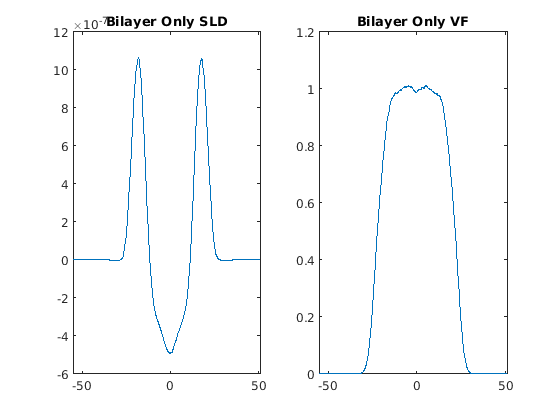

% Calculate total volume fraction of bilayer only (neglecting water)
sumSLD = zeros(length(z),1);    % Array for total SLD
sumVF = zeros(length(z),1);     % Array for total VF
for i = 1:6
    sumSLD = sumSLD + sld(:,i);
end

% For the volume fractions (probabilities), we just use our calcProbs
% function with our fitted volumes..
bilnd = nTot(:,1:6);       %Water is at the end of the array...
vols = fitVols(1:6);
[allProbs,sumVF] = calcProbs(z,bilnd,vols);

% We make an array of each with our z values. But, we need to centre the 
% bilayer at 0, so subtract 56 Angstrom from z to centre it.
z = z - 56;

% And make our two arrays
bilayerSLD = [z sumSLD];
bilayerVF = [z sumVF];

figure(4); clf;
subplot(1,2,1); box('on'); hold on
plot(bilayerSLD(:,1),bilayerSLD(:,2));
title('Bilayer Only SLD');

subplot(1,2,2); box('on'); hold('on')
plot(bilayerVF(:,1),bilayerVF(:,2));
title('Bilayer Only VF')

These are the only two bilayer inputs required for the data fitting step. This pre-processing is done before fitting, and then we  usually save them to a file for the next step.

dppc.SLD = bilayerSLD;
dppc.VF = bilayerVF;
save('dppc.mat','dppc');


## *Building Up a Complete Model of the Interface to Calculate Reflectivity.*

We consider the simplet possible case of a DPPC bilayer on Silicon, under 3 water contrasts. We want to calculate the SLD (and then reflectivity) of this system, which we then use fit to the data. The bilayer signal is as per the pre-processing described above.

The overall system is submerged, and the key thing to rebember that and part of the stck not taken up by membrane or substrate. In oter words, any free volume in the system will be water. We will build the system in stages to illustrate the key principles.

### *Substrate*

Considering the substrate, silicon is not purous, and so the volume fraction occupied by bulk Silicon will be 1. There may be incomplete coverage of oxide, so some of the SiO2 layer may in fact be holes, which because the system is submerged, these holes will be filled with water. Also, we know that no real solid is a mathematically sharp interface, instead there is always a finite surface roughness. We deal with this by representing the surface of the Silicon by an error function.

Starting with the volume fraction of Silicon, because the Silicon must occupy all available volume, VF of bulk Silicon must be 1. Away from the Silicon the VF of Silicon must be zero. The transition from one to the other is an error function, as follows :-

% Start by defining a z-range for our whole model. 200 Angstroms should be
% fine:
z = 1:200;              % Range of model in angstroms

% Define the Silicon in terms of it's volume fraction, position, width and
% roughness.
r = 3;                  % RMS roughness of Si Surface
h = 1                   % Volume fraction of bulk Silicon

h = 1

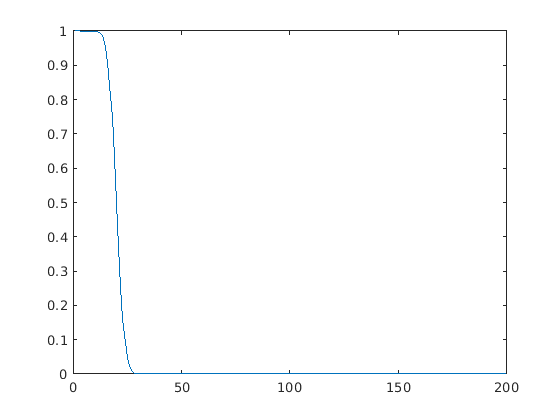

bulk_si_VF = 1;         % Volume fraction of bulk Silicon
roughness = 3;          % width or error functions (roughness)
siCentre = 0;           % Centre of Silicon box
siWidth = 40;           % Total Width of Silicon box

% Make the Silicon volume fraction box
siVF = asymconvstep(z,siWidth,siCentre,roughness,roughness,bulk_si_VF);

% Plot this out just to see.
figure;
plot(z,siVF)

This represents the volume fraction of Silicon. To illustrate the principle of how we go to SLD from here, if we wanted to get the volume fraction of water, then because in this simple picture, anything that is not Silicon must be water, then VFwater must be:

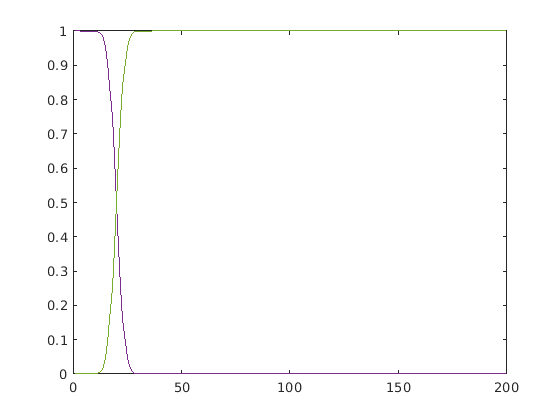

waterVF = 1 - siVF;
figure(5); box on; hold on
plot(z,siVF,z,waterVF)

This gives up the VF of Silicon and water in our range. To convert these to SLD, then we can simply multiply the volume fractions for each by their bulk SLD..

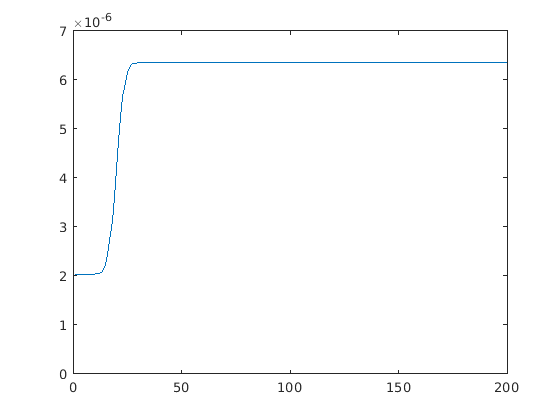

bulk_Si_SLD = 2.037e-6;
bulk_D2O_SLD = 6.35e-6;     % D2O

sld_Si = siVF * bulk_Si_SLD;
sld_D2O = waterVF * bulk_D2O_SLD;

% And the total SLD is just the sum of both...
totSLD = sld_Si + sld_D2O;

figure; plot(z,totSLD); ylim([0 7e-6]);

This illustrates the principle of how we will build up the whole system: work out the volume fraction of everything, add them all up, and anything left is water.

Now let's add the oxide. First make a box representing complete coverage of oxide:

% Define oxide width
width_Oxide = 20;

% We need it's centre relative to the Silicon surface
siSurf = siCentre + (siWidth/2);

% The centre of the oxide is 0.5 the total oxide width away
oxCentre = siSurf + (width_Oxide / 2);

% Then for full coverage, the Oxide layer box will be
oxVF = asymconvstep(z,width_Oxide,oxCentre,roughness,roughness,1);

To deal with less than full coverage, we can just multiply the oxide VF by the fractional coverage. Then, when we calculate the water volume fraction, some water will appear in the oxide layer.

oxCoverage = 0.9;   % 90% coverage of oxide

%Adjust the oxide VF
oxVF = oxVF * oxCoverage;

% Find the total volume fraction of our system.
totalVF = siVF + oxVF;

% Then as before, the water is everything else
waterVF = 1 - totalVF;

Plot everything out to see what we have....

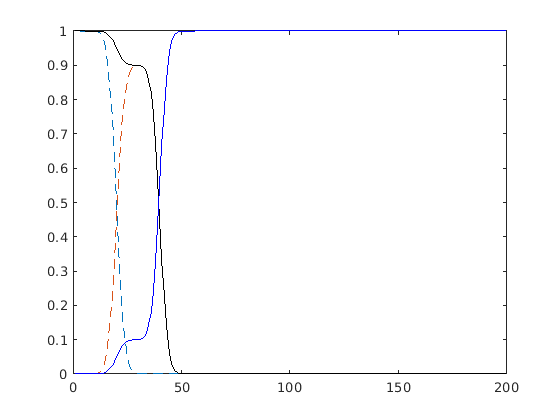

figure(6); clf; hold on; box on
plot(z,siVF,'--');
plot(z,oxVF,'--');
plot(z,totalVF,'k-');
plot(z,waterVF,'b-');

Notice how the water VF does not decrease to zero in the oxide layer (i.e. holes in the SiO2 are filled with water). To the the SLD profile, we multiply by the bulk SLD as before..

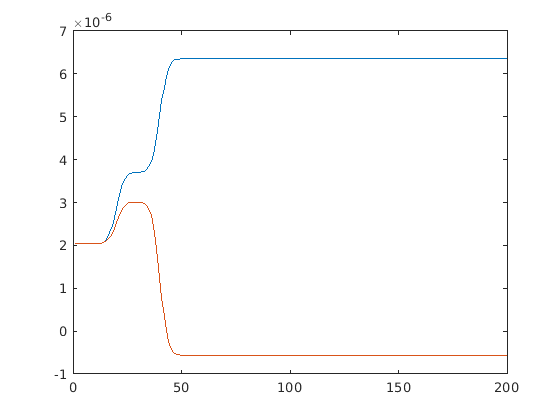

bulk_oxide_SLD = 3.41e-6;

sld_Si = siVF * bulk_Si_SLD;
sld_Oxide = oxVF * bulk_oxide_SLD;

% This time, we'll look at the total at two different water contrasts: D2O
% and H2O
bulk_D2O_SLD = 6.35e-6;
bulk_H2O_SLD = -0.56e-6;

totalSLD_D2O = (siVF * bulk_Si_SLD) + (oxVF * bulk_oxide_SLD) + (waterVF * bulk_D2O_SLD);
totalSLD_H2O = (siVF * bulk_Si_SLD) + (oxVF * bulk_oxide_SLD) + (waterVF * bulk_H2O_SLD);

figure(7); clf; box on; hold on
plot(z,totalSLD_D2O);
plot(z,totalSLD_H2O);

These SLD profiles completely describe or substrate from a neutron perspective. The key point is that our substrate is defined in terms of three parameters; the substrate roughness, the oxide thickness and the oxide coverage. When we fit data, these three would need to be fitting parameters (although in practice, there are other instrument specific parameters we would need to consider, sich as resolution and instrument background). In the next section, we deal with adding the membrane to this.

### *Adding the Bilayer*

From the discussion above of how to buld the substrate layers, it should be fairly obvious that to add the bilayer we do so using the volume fraction that we calculated when processing the MD simulation in the first section. We use a coverage parameter as is the case for the oxide (samples are rarely totally complete), but there is also one more correction that is required.

The bilayers that we use are known as 'floating bilayers', because rather than sticking directly to the substrate, they 'float' a certain distance away, resulting in a large cushion of water netween the substrate layers an the membrane. The bilayer is held in place by Van der Waals forces (or also electrostatics if there are charges), but this is balanced by a repulsive entropic pressure. The reason for this is that all bilayers, being flexible membranes, have a tendency to fluctuate (you can think of this roughly as Brownian motion acting on a flexible sheet).  If the membrane is stuck directly to the substrate, this reduces the possible fluctuation amplitudes of the membrane, which results in a decrease of the entropy of the system (in Boltzman terms). Like all things, the system has a desire for maximal entropy, and this manifests as a repulsive pressure (known as the Helfrich force), where the bilayer moves away from the substrate to a position where it can maximise it's configurational entropy. The balance between the attractive VdW and the repulsive Helfrich pressure results in a potential well, some distance from the substrate, where the bilayer sits. In practice we acheive this by tuning the coatings that we apply to the substrate (usually we coat them with lipids) - the VdW with bare silicon is too large, so these samples do tend to stick. The advantage of this is that floating bilayers are not constrained by frictional effects with the substrate, and we get realistic diffusion constants, phase behaviours and so on for the lipids in the membrane.

The fluctuations are much larger in amplitude than those obtained from the MD simulation. In terms of the SLD profile, the effect is to 'smear' the SLD and Volume Fraction profiles that we calculated in step 1. We have found that an effective way of modelling this is to convolute the bilayer curves with a Gaussian, as follows:

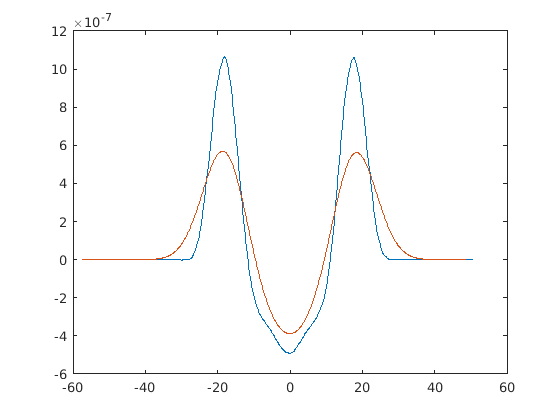

% We need the SLD profile of the membrane that we calculated in part 1
% (bilayerSLD), but we also need a Gaussian for the convolution.
% Our bilayer is centred at zero in z, we need a Gaussian centred at the
% same value. We assume the fluctuation amplitude of the membrane is 2
% Angstroms (in reality this is another fitting parameter).

% First, make the Gaussian....
bilayerRough = 5;           % Gausian 1/e width
filter = Gaussian(bilayerSLD(:,1),0,1,bilayerRough);
filter = [bilayerSLD(:,1),filter(:)];

% Now do the convolution...
% res = sld_convolute(signal,filter)
convBilayer = sld_convolute(bilayerSLD,filter);

% Plot these to see the result..
figure(8); clf; hold on; box on;
plot(bilayerSLD(:,1),bilayerSLD(:,2));
plot(convBilayer(:,1),convBilayer(:,2));

In other words, the effect of fluctuation (and convolution) is to 'smear' the membrane signal in z. We also need to do the same thing with the volume fraction:

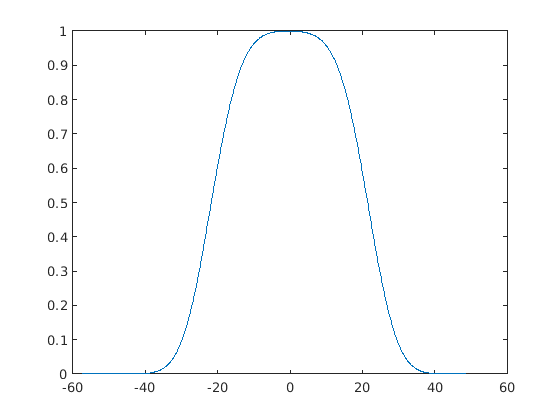

convBilVolume = sld_convolute(bilayerVF ,filter);
figure(9); clf; hold on; box on
plot(convBilVolume(:,1),convBilVolume(:,2));

To deal with a less than full coberage of bilayer, we simply multiply these by the fractional coverage (as for the Oxide)..

bilayerCoverage = 0.9;     % This is 90% coverage of the membrane

convBilayer(:,2) = convBilayer(:,2) * bilayerCoverage;
convBilVolume(:,2) = convBilVolume(:,2) * bilayerCoverage;

To build the complete model, we first position the the bilayer occupied volume within our overall volume fraction for the wholse system. We usually define this position relatibe to the surface of the oxide..

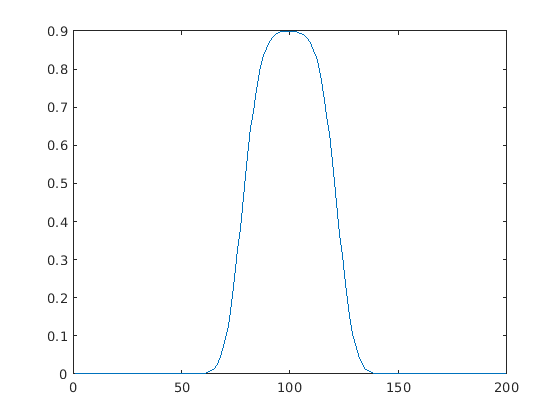

oxideSurf = siSurf + width_Oxide;
bilayerPosition = 60;                       % Pos Relative to oxide surface 
bilCentre = oxideSurf + bilayerPosition;    % Absolute position in z

% Because our bilayer is centered at zero, we just add this to the x fo our
% bilayer, both for the SLD and volume
convBilayer(:,1) = convBilayer(:,1) + bilCentre;
convBilVolume(:,1) = convBilVolume(:,1) + bilCentre;

% To Work out the total volume fraction including the bilayer,
% we first have to interpolate bilayer on the same scale as everything else
% (i.e. versus z). We also need to do the same thing with the SLD.
bilVF = interpolateOnToZ(convBilVolume(:,1),convBilVolume(:,2),z);

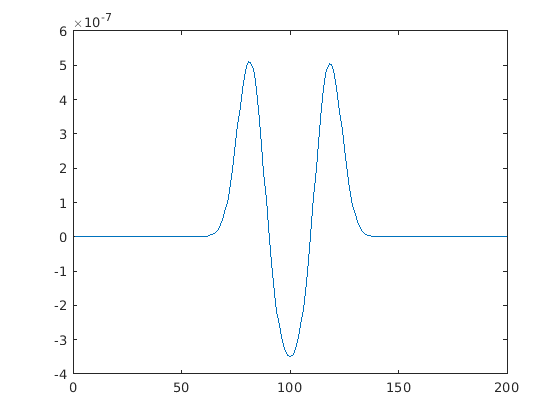

bilSLD = interpolateOnToZ(convBilayer(:,1),convBilayer(:,2),z);


% The total volume occupied along the whole interface is now given by
% the sum of all our volume fractions, this time including the bilayer
totalVF = siVF + oxVF + bilVF;

% And  as before, water volume fraction is given by what's left
waterVF = 1 - totalVF;

% Plot all this out..
figure(9); clf; hold on; box on
plot(z,siVF,'--');
plot(z,oxVF,'--');
plot(z,bilVF,'--');
plot(z,totalVF,'k--');
plot(z,waterVF,'b--');
plot(z,totalVF,'k-');

Now that we have all the volume fractions, we can get the SLD's as the sum of the SLD's of the individual components. As is the case for the Silicon and Oxide, the SLD of the water is obtained by multiplying the VF of water by the relevant SLD of the water. But, we normally measure the sample against at least three water contrasts (i.e. three different mixtures of D2O and H2O). The reason for this is that reflectivity is non unique - there can be multiple SLD profiles that give the same data. This is because reflectivity is calculated from the square of the Fresnel reflection coefficients and so phase information is lost (the reflectivity equivalent of the Diffraction 'phase problem'). For this reason it's not possible to do 'direct inversion' of reflectivity data back to an SLD, and we can only find the structure by data fitting. By having different deuterations, we have to find a structural solution that satisfies the data simultaneously for multiple contrasts, which in the limit of enough deuterations tends to a unique solution.

% Calculate the water SLD at three contrasts
SLD_H2O = waterVF * -0.56e-6;
SLD_D2O = waterVF * 6.35e-6;
SLD_mix = waterVF * 4e-6;       %SLD of some intermediate mixture.

sldTotal_D2O = (siVF*bulk_Si_SLD) + (oxVF*bulk_oxide_SLD) + bilSLD + (SLD_D2O);
sldTotal_mix = (siVF*bulk_Si_SLD) + (oxVF*bulk_oxide_SLD) + bilSLD + (SLD_mix);
sldTotal_H2O = (siVF*bulk_Si_SLD) + (oxVF*bulk_oxide_SLD) + bilSLD + (SLD_H2O);

figure(10); clf; hold on; box on
plot(z,sldTotal_D2O);
plot(z,sldTotal_mix);
plot(z,sldTotal_H2O);

Despite being from the same sample, these lead to three very different Reflectivity profiles (we will talk about how these are calculated in the next worksheet). To analyse the data, with our simple model we have 6 fitting parameters:

Substrate roughness,

Oxide Thickness,

Oxide coverage,

Bilayer position,

Bilayer roughness,

Bilayer coverage.

Fitting our data will therefore involve finding optimum values of these 6 parameters to as to best reproduce our measurements. In practice (for real samples), there are additional substrate layers and instrumental parameters (such as instrument resolution), so we fit more parameters than just these 6. You can see a complete example of using this to fit data from DPPC using a structure from an MD simulation in [4].

[1] H.I. Petrache, S. E. Feller and J. F. Nagle, Biophys. J., 72(5), p 2237 (1997)

[2] Wiener and White, Biophys. J., 61, p 437 (1992).

[3] R. S. Armen, O. D. Uitto, and S. E. Feller, Biophys. J., 75(2), p 734 (1998)

[4] A. V. Hughes et al, Acta. Cryst., D72, p1227 (2016).

## *Function Definitions*

function [allProbs,totProb] = calcProbs(z,nTot,volumes)
% This function calculates the quantity given
% in the LHS of equation (5).
%
% Inputs:
% z = the array of z values of the box. It's length is the number of slices (Angstroms)
% nTot = array of the individual number densities for each component as a function
%        of z.It has size [length(z) x numberOfDistributions]
% volumes = array of fragment volumes.
%
% Outputs:
% allProbs = An array of the probabilities for each component as a function of
%            z. It has size [length(z) x numberOfDistributions]
% totProb = Sum over all nTot for all components. It has dimensions [length(z) x 1]  


numDists = length(volumes);  % Number of components

% Pre-allocation of totProb so that the sum in the loop works.
totProb = zeros(length(z),1);

for i = 1:numDists
    allProbs(:,i) = nTot(:,i)*volumes(i);
    totProb = totProb + allProbs(:,i);
end

end

% ------------------------------------------------------------------------------------

function chi = fitFun(vols)
% This is the function that is minimised duting the fit. It takes the
% volumes of the components as an input array, retrieves the other
% parameters required form the Matlab base workspace (it does this once and
% assignes them to persistent variables for speed). The value of the total
% probabilty should be 1 at all points along z for a perfect fit. So
% in order to calculate the goodness of fit, it works out chi-squared
% between the calculated probability and a straight line at p = 1. This
% is then returned to the simplex.

persistent z nTot

% If this is the first time the function is called, the persistent
% variables will be empty. If so, load in the relevant values.
if isempty(z)
    z = getappdata(0,'z');
    nTot = getappdata(0,'nTot');
end

% Calculate the probabilities from the inputted volumes
[probs,totProb] = calcProbs(z,nTot,vols);

% Calculate chi-squared between the total probability and a 'perfect'
% p = 1 line.
perfectFit = ones(length(z),1);
chi = chi_squared(totProb,perfectFit,length(vols));

end

% -------------------------------------------------------------------------------

function chi2 = chi_squared(fit,y,P,eb)
% chi_squared(func,data,numparams,errors)
%
% returns *reduced* chi^2 value for use in data modelling
% "y" is a vector of data, "fit" is a vector of model values (size(fit)=size(y)), P is the number of
% parameters fit in the model, and eb is a vector of error bars (1-to-1 correspondnce with y)
% Ref: John R. Taylor, "An Introduction to Error Analysis", (2nd ed., 1997)
%
% 11/11/01 Mike Scarpulla.  Please direct questions or comments to scarps@uclink.berkeley.edu

if nargin<3
    error('Wrong number of arguments passed to "chi_squared"')
end

% if error bars are not availible, evaluate chi^2 by normalizing deviation^2 by magnitude of data.
% This assumes that the STDEV of a value scales as SQRT(value).  USE WITH THIS CAVEAT IN MIND
if nargin==3
    N = max(size(y));
    terms = ((y-fit).^2)./abs(y);
    chi2 = 1/(N-P)*sum(terms);
end

%if error bars are availible, normalize the deviation to the expectred error
if nargin==4
   N = max(size(y));
   if N <= P
      N = (P + 1);
   end
  	 terms = ((y-fit)./eb).^2;
    chi2 = 1/(N-P)*sum(terms);
end

end

% ----------------------------------------------------------------------------------------------------

function f = asymconvstep(z,zw,zcen,s1,s2,h)
% Produces a step function convoluted with differnt error functions
% on each side.
%
% AsymConvstep (z,zw,xcen,s1,s2,h)
%       z = vector of x values
%      zw = Width of step function
%    zcen = Centre point of step function
%       s1 = Roughness parameter of left side
%       s2 = Roughness parameter of right side
%       h = Height of step function.

% Since the step is defined in terms of it's centre
% and its width, we find the edges as centre +/- 0.5 width.
r = zcen + (zw/2);          % Right edge
l = zcen - (zw/2);          % Left edge

% Make the box
a = (z-l)./((2^0.5)*s1);
b = (z-r)./((2^0.5)*s2);
f = (h/2)*(erf(a)-erf(b));

end

% -----------------------------------------------------------------

function res = sld_convolute(signal,filter)

% This function convolutes the signal (in our case the bilayer SLD or volume) with a
% filter (in our case a Gaussian). Broadly speaking, the procedure is to
% take the Fourier transform of both curves, multiply those together, and
% inverse fourier transform the result, although there are a number of
% numerical correction steps that are required first:
%
%   1. Interpolate both curves onto the same x 'grid'
%   2. Ensure that both curves are zero at each end (called 'normalisation'
%   here)
%   3. Pad each curve with zeros at each end, the length of which is equal
%   to the sum of the lengths of both curves.
%   4. Do the convolution usign Matlab's 'conv' function.
%   5. Undo the corrections done in steps 1 to 3 on the convoluted curve to get the final result. 
 
debug = 0;          % flag for debug plot if required

%Interpolate signals onto uniform grid....
%sld....
sld_x = signal(:,1);
sld_y = signal(:,2);

st = sld_x(1);
en = sld_x(end);
newSldX = linspace(st,en,length(sld_y));
newSldY = interp1(sld_x,sld_y,newSldX);
new_sld = [newSldX(:) newSldY(:)];

%also filter....
filt_x = filter(:,1);
filt_y = filter(:,2);

st = filt_x(1);
en = filt_y(end);
newFiltX = linspace(st,en,length(filt_y));
newFiltY = interp1(filt_x,filt_y,newSldX);
new_filt = [newFiltX(:) newFiltY(:)];

%Need to pad the edge of the signal with zeros. Do this by padding out
%initially with the values at the edges, then 'normalise' the
%water regions to zero buy subtraction...
yStart = newSldY(1);
xStep = abs(newSldX(2)-newSldX(1));

%Do the zero padding.... 
padLength = (length(filter) + length(newSldX));
padStartX = (padLength*(-xStep))+newSldX(1);
padLeftX = linspace(padStartX,(newSldX(1)-xStep),padLength);
padEndX = padLength*(xStep)+newSldX(end);
padRightX = linspace((newSldX(end)+xStep),padEndX,padLength);
yPad = ones(1,padLength)*yStart;

%Make the 'spliced' data
padNewX = [padLeftX newSldX padRightX];
padNewY = [yPad newSldY yPad];

%....'normalise' to give zero edges...
yDivFactor = newSldY(1);
padNewY = padNewY - newSldY(1);

sigFactor = sum(newFiltY);
yFactor = sum(padNewY);
newFilter = newFiltY ./ sigFactor;
padNewY = padNewY ./ yFactor; 

%Then convolute... 
fConv = conv(padNewY,newFilter,'same');
fConv_preNorm = fConv;

%Finally 'denormalise' to get the result.... 
%padNewY = (padNewY.*yFactor) + yDivFactor;
fConv = (fConv.*yFactor) + yDivFactor;

switch debug
    case 1
        figure(100)
        clf
        plot(padNewX,fConv,'k--')
        hold on
        plot(newSldX,newSldY);
end

%Trim back to original size
stPoint = padLength;
endPoint = length(padNewX)-(padLength-1);

offset = 2;

finalX = padNewX(stPoint:endPoint) - offset;  %Not sure where this offset comes from - bug with the padding somewhere..
finalY = fConv(stPoint:endPoint);
res = [finalX(:) finalY(:)];

end

% ---------------------------------------------------------------------------------------------------


function f = Gaussian(z,Z,N,A)
%f(z) = gaussian(z,Z,N,A)
%
%	produces a gaussian at centre Z, of height
%	N and 1/e half width of A.

f = (N/(A*sqrt(pi)))*exp(-0.5*((z-Z).^2)/(A^2));

end

% ---------------------------------------------------------------------------------------------------

function [newY] = interpolateOnToZ(X,Y,z)

% Interpolates the curve given by [X Y] onto Z.
% It first extends the range of X and Y to cover the 
% whole range of z, otherwise Matlab's interp1 will
% return NaN when beyond the range of the original X

debug = 1;

% Pad out the lower end of X and Y
xLeftEdge = X(1);
xLeftPad = linspace(0,floor(xLeftEdge));
yLeftPad = zeros(length(xLeftPad),1);

% Do the same for the upper edge
xRightEdge = X(end);
if (max(z)-xRightEdge)<=10
    xRightPad = max(z);
else
    xRightPad = linspace(ceil(xRightEdge),max(z));
end
yRightPad = zeros(length(xRightPad),1);

extendedX = [xLeftPad(:) ; X(:) ; xRightPad(:)];
extendedY = [yLeftPad(:) ; Y(:) ; yRightPad(:)];

%Interpolate them onto z....
newY = interp1(extendedX,extendedY,z);

% Debug plot
if debug == 1
    figure(); clf
    clf
    plot(z,newY)
end

end